% Test script for detecting squares, circles, and crosses on a Tic Tac Toe board

% --- Preprocess the Image ---
% Use the function to preprocess the image (smooth lines and make them skinnier)
preprocessed_image = A2_imageProcess('A2_testing14.jpg');

% --- Detect Square Centers ---
% Call the function to detect square centers
square_centers = A2_detectSquareCenters(preprocessed_image);

% --- Detect Circles ---
% Call the function to detect circles
circle_centers = A2_find_circles(preprocessed_image);

% --- Detect Crosses ---
% Call the function to detect crosses
cross_centers = A2_find_crosses(preprocessed_image);

% --- Update the Board Matrix ---
% Fill the board matrix with detected shapes
A2_boardMatrixFill(square_centers, cross_centers, circle_centers);


Current Board:
 . | . | .
---+---+---
 X | O | O
---+---+---
 . | O | X




% --- Display the Results ---
figure;
imshow(preprocessed_image);
hold on;
title('Detected Square Centers, Circles, and Crosses');

% Plot the detected square centers (green circles)
if ~isempty(square_centers)
    plot(square_centers(:, 1), square_centers(:, 2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
    disp('Detected Square Centers:');
    disp(array2table(square_centers, 'VariableNames', {'X_Coordinate', 'Y_Coordinate'}));
else
    disp('No Square Centers Detected');
end

Detected Square Centers:


    X_Coordinate    Y_Coordinate
    ____________    ____________

       191.73          105.89   
       348.27          105.89   
       504.82          105.89   
       191.73          206.63   
       348.27          206.63   
       504.82          206.63   
       191.73          307.37   
       348.27          307.37   
       504.82          307.37   




% Plot the detected circles (red circles)
if ~isempty(circle_centers)
    plot(circle_centers(:, 1), circle_centers(:, 2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    disp('Detected Circle Centers:');
    disp(array2table(circle_centers, 'VariableNames', {'X_Coordinate', 'Y_Coordinate'}));
else
    disp('No Circles Detected');
end

Detected Circle Centers:


    X_Coordinate    Y_Coordinate
    ____________    ____________

       337.65          294.34   
       490.66          207.89   
       336.09          207.62   




% Plot the detected crosses (blue X's)
if ~isempty(cross_centers)
    plot(cross_centers(:, 1), cross_centers(:, 2), 'bx', 'MarkerSize', 10, 'LineWidth', 2);
    disp('Detected Cross Centers:');
    disp(array2table(cross_centers, 'VariableNames', {'X_Coordinate', 'Y_Coordinate'}));
else
    disp('No Cross Centers Detected');
end

Detected Cross Centers:


    X_Coordinate    Y_Coordinate
    ____________    ____________

        468             303     
        219             205     
        336             256     



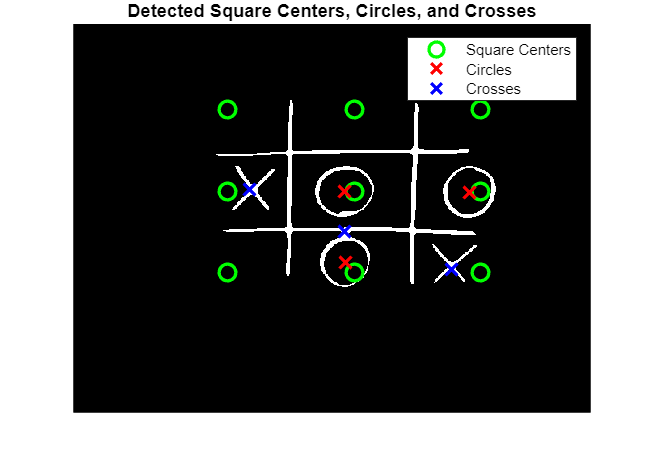


legend('Square Centers', 'Circles', 'Crosses');
hold off;